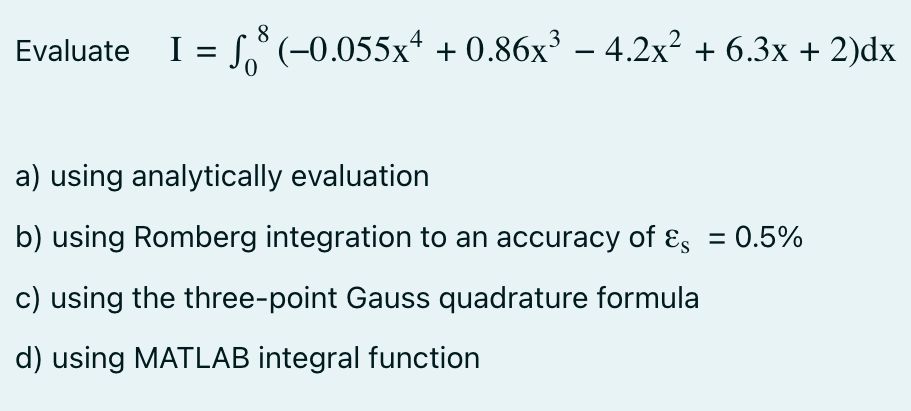

f1 = @(x) -0.055 * x.^4 + 0.86 * x.^3 - 4.2 * x.^2 + 6.3 * x + 2;
a = 0;
b = 8;

p = [-0.055 0.86 -4.2 6.3 2];
q = polyint(p);
I_true = diff(polyval(q, [a b]))

I_true = 20.9920

[I_rom, ea, iter] = romberg(f1, 0, 8, 0.5); %es = 0.5%
I_romberg = I_rom

I_romberg = 20.9920

a1 = (b + a) / 2;
a2 = (b - a) / 2;
f2 = @(xd) (-0.055 * (a1 + a2 .* xd) .^ 4 + 0.86 * (a1 + a2 .* xd) .^ 3 - 4.2 * (a1 + a2 .* xd) .^ 2 + 6.3 * (a1 + a2 .* xd) + 2) * a2;

% three-point
c0 = 5/9;
c1 = 8/9;
c2 = 5/9;
x0 = -sqrt(3/5);
x1 = 0.0;
x2 = sqrt(3/5);
I_gauss = c0 * f2(x0) + c1 * f2(x1) + c2 * f2(x2)

I_gauss = 20.9920

i_integral = integral(f1, a, b)

i_integral = 20.9920